n = 6;                   % Number of total Nodes
L_tot = 9.4; % [m]       % Total length of shaft
L = L_tot/(n-1);             % Length Of each node
r_s = 0.3;              % shaft radius
rho_s = 7850;            % shaft density
E = 200e9;                % Young Modules
nu = 0.3;

omega = 1;
rotor = 'simple MGT-70'

rotor = 'simple MGT-70'

pi = 3.1415;
S = pi*r_s^2;             % Shaft Cross section Area
I = pi*r_s^4/4;
if strcmp(rotor,'Compressor/turbine')
    n_shaft = 1:n-1;
    r_s_more = 1.4*[0.11 0.14 0.16 0.13 0.13 0.12 0.11 0.11 0.17 0.15 0.15 0.11 0.13 0.12 0.12 0.17 0.17 0.2 0.2];  % Shaft has variable diameter(manually adjustable)
elseif strcmp(rotor, 'Jeffcott')
    n_shaft = 1:n-1;
    r_s_more = r_s*ones(1,n-1);
elseif strcmp(rotor,'simple MGT-70')
    n_shaft = 1:n-1;
    r_s_more = r_s*ones(1,n-1);
end

S_more = pi.*r_s_more.^2;
I_more = pi.*r_s_more.^4/4;
r_s_vec = r_s*ones(1,n);
I_vec = I*ones(1,n);
S_vec = S*ones(1,n);
size_n_shaf = size(n_shaft);
for i_shaf = 1:size_n_shaf(2)
    I_vec(1,n_shaft(i_shaf)) = I_more(i_shaf);
    S_vec(1,n_shaft(i_shaf)) = S_more(i_shaf);
    r_s_vec(1,n_shaft(i_shaf)) = r_s_more(i_shaf);
end

M_ref = [156    0     0     -22*L   54    0     0      13*L;
         0      156   22*L   0      0     54   -13*L   0;
         0      22*L  4*L^2  0      0     13*L -3*L^2  0;
        -22*L   0     0      4*L^2 -13*L  0     0     -3*L^2;
         54     0     0     -13*L   156   0     0      22*L;
         0      54    13*L   0      0     156  -22*L   0;
         0     -13*L -3*L^2  0      0    -22*L  4*L^2  0;
         13*L   0     0     -3*L^2  22*L  0     0      4*L^2]*rho_s*S*L/420

M_ref = 1.0e+03 *

    1.5498         0         0   -0.4109    0.5365         0         0    0.2428
         0    1.5498    0.4109         0         0    0.5365   -0.2428         0
         0    0.4109    0.1405         0         0    0.2428   -0.1053         0
   -0.4109         0         0    0.1405   -0.2428         0         0   -0.1053
    0.5365         0         0   -0.2428    1.5498         0         0    0.4109
         0    0.5365    0.2428         0         0    1.5498   -0.4109         0
         0   -0.2428   -0.1053         0         0   -0.4109    0.1405         0
    0.2428         0         0   -0.1053    0.4109         0         0    0.1405



M_s = [36   0    0     -3*L   -36   0       0     -3*L;
       0    36   3*L    0      0   -36      3*L    0;
       0    3*L  4*L^2  0      0   -3*L    -L^2    0;
      -3*L  0    0      4*L^2  3*L  0       0     -L^2;
      -36   0    0      3*L    36   0       0      3*L;
       0   -36  -3*L    0      0    36     -3*L    0;
       0    3*L -L^2    0      0   -3*L     4*L^2  0;
      -3*L  0    0     -L^2    3*L  0       0      4*L^2]*rho_s*I/(30*L)

M_s =    31.8754         0         0   -4.9938  -31.8754         0         0   -4.9938
         0   31.8754    4.9938         0         0  -31.8754    4.9938         0
         0    4.9938   12.5178         0         0   -4.9938   -3.1295         0
   -4.9938         0         0   12.5178    4.9938         0         0   -3.1295
  -31.8754         0         0    4.9938   31.8754         0         0    4.9938
         0  -31.8754   -4.9938         0         0   31.8754   -4.9938         0
         0    4.9938   -3.1295         0         0   -4.9938   12.5178         0
   -4.9938         0         0   -3.1295    4.9938         0         0   12.5178



M = zeros(n*4);

for k = 0:n
    if 1+k*4 < n*4 - 4
        for i = 0:7
            for j = 0:7
                M(1+k*4+i,1+k*4+j) = M(1+k*4+i,1+k*4+j) + S_vec(k+1)*M_ref(1+i,1+j)/S +  I_vec(k+1)*M_s(1+i,1+j)/I;
            end
        end
    end
end
M

M = 1.0e+03 *

    1.5817         0         0   -0.4159    0.5046         0         0    0.2378         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.5817    0.4159         0         0    0.5046   -0.2378         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.4159    0.1530         0         0    0.2378   -0.1085         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.4159         0         0    0.1530   -0.2378         0         0   -0.1085         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5046         0 


% ============== DISK ================
if strcmp(rotor,'Compressor/turbine')
    n_dis = [4 5 6 7 8 17 18 19];
    r_d_more = [1.7 1.5 1.4 1.3 1.2 1 1.1 1.2];
    b_d_more = [0.17 0.15 0.14 0.13 0.12 0.1 0.12 0.14];
elseif strcmp(rotor,'Jeffcott')
    n_dis = round(n/2);
    r_d_more = 1;
    b_d_more = 0.15;
elseif strcmp(rotor,'simple MGT-70')
    n_dis = [3 4];
    r_d_more = [1 1.25];
    b_d_more = [0.2 0.2];
end
rho_d = 7850;
D_d_more = r_d_more*2;
V_d_more = b_d_more.*pi.*D_d_more.^2/4;
M_D_more = rho_d.*V_d_more;
I_Dx_more = 0.25*M_D_more.*r_d_more.^2  +  (1/12)*M_D_more.*b_d_more.^2;
I_Dy_more =  0.5*M_D_more.*r_d_more.^2;

I_Dx_vec = zeros(1,n);
I_Dy_vec = zeros(1,n);
r_d_vec = zeros(1,n);
b_d_vec = zeros(1,n);
size_n_dis = size(n_dis);
for i_disk = 1:size_n_dis(2)
    I_Dx_vec(1,n_dis(i_disk)) = I_Dx_more(i_disk);
    I_Dy_vec(1,n_dis(i_disk)) = I_Dy_more(i_disk);
    r_d_vec(1,n_dis(i_disk)) = r_d_more(i_disk);
    D_d_vec = r_d_vec*2;
    b_d_vec(1,n_dis(i_disk)) = b_d_more(i_disk);
    V_d_vec = pi*b_d_vec.*D_d_vec.^2/4;
    M_D_vec = rho_d.*V_d_vec;
end

for p = 1:n
    M_disk = [M_D_vec(p);M_D_vec(p);I_Dx_vec(p);I_Dx_vec(p)].*eye(4);
    for i = 0:3
        for j = 0:3
            M(1+(p-1)*4+i,1+(p-1)*4+j)= M(1+(p-1)*4+i,1+(p-1)*4+j) + M_disk(1+i,1+j);
        end
    end
end

% ============== SHAFT AND DISK Gyroscopic Matrix ================
% C_disk = [0 0 0    0;
%           0 0 0    0;
%           0 0 0   -I_Dy;
%           0 0 I_Dy 0]*omega;

C_ref = [0   -36  -3*L    0      0    36     -3*L    0;
         36   0    0     -3*L   -36   0       0     -3*L;
         3*L  0    0     -4*L^2 -3*L  0       0      L^2;
         0    3*L  4*L^2  0      0   -3*L    -L^2    0;
         0    36   3*L    0      0   -36      3*L    0;
        -36   0    0      3*L    36   0       0      3*L;
         3*L  0    0      L^2   -3*L  0       0     -4*L^2;
         0    3*L -L^2    0      0   -3*L     4*L^2  0]*(rho_s*I*omega/(15*L))

C_ref =          0  -63.7507   -9.9876         0         0   63.7507   -9.9876         0
   63.7507         0         0   -9.9876  -63.7507         0         0   -9.9876
    9.9876         0         0  -25.0356   -9.9876         0         0    6.2589
         0    9.9876   25.0356         0         0   -9.9876   -6.2589         0
         0   63.7507    9.9876         0         0  -63.7507    9.9876         0
  -63.7507         0         0    9.9876   63.7507         0         0    9.9876
    9.9876         0         0    6.2589   -9.9876         0         0  -25.0356
         0    9.9876   -6.2589         0         0   -9.9876   25.0356         0




C = zeros(n*4);
for k = 0:n
    if 1+k*4 < n*4 - 4
        for i = 0:7
            for j = 0:7
                C(1+k*4+i,1+k*4+j)=C(1+k*4+i,1+k*4+j)+I_vec(k+1)*C_ref(1+i,1+j)/I;
            end
        end
    end
end

for k = 0:n
    if 1+k*4 < n*4 - 4
        C_disk = [0 0 0             0;
                  0 0 0             0;
                  0 0 0            -I_Dy_vec(k+1);
                  0 0 I_Dy_vec(k+1) 0]*omega;
        
        for i = 0:3
            for j = 0:3
                C(1+k*4+i,1+k*4+j)= C(1+k*4+i,1+k*4+j) + C_disk(1+i,1+j);
            end
        end
    end
end
S_r = S;
G = E/(2*(1 + nu));
a = (12*E*I)/(G*S_r*L^2);
K_C = [12   0    0        -6*L      -12     0     0        -6*L;
    0    12   6*L       0         0     -12    6*L       0;
    0    6*L (4+a)*L^2  0         0     -6*L  (2-a)*L^2  0;
    -6*L  0    0        (4+a)*L^2  6*L    0     0        (2-a)*L^2;
    -12   0    0         6*L       12     0     0         6*L;
    0   -12  -6*L       0         0      12   -6*L       0;
    0    6*L (2-a)*L^2  0         0     -6*L  (4+a)*L^2  0;
    -6*L  0    0        (2-a)*L^2  6*L    0     0        (4+a)*L^2;]*E*I/((1+a)*L^3)

K_C = 1.0e+09 *

    1.9170         0         0   -1.8020   -1.9170         0         0   -1.8020
         0    1.9170    1.8020         0         0   -1.9170    1.8020         0
         0    1.8020    2.3706         0         0   -1.8020    1.0171         0
   -1.8020         0         0    2.3706    1.8020         0         0    1.0171
   -1.9170         0         0    1.8020    1.9170         0         0    1.8020
         0   -1.9170   -1.8020         0         0    1.9170   -1.8020         0
         0    1.8020    1.0171         0         0   -1.8020    2.3706         0
   -1.8020         0         0    1.0171    1.8020         0         0    2.3706



F = 0;
K_F = [36   0    0     -3*L   -36   0       0     -3*L;
    0    36   3*L    0      0   -36      3*L    0;
    0    3*L  4*L^2  0      0   -3*L    -L^2    0;
    -3*L  0    0      4*L^2  3*L  0       0     -L^2;
    -36   0    0      3*L    36   0       0      3*L;
    0   -36  -3*L    0      0    36     -3*L    0;
    0    3*L -L^2    0      0   -3*L     4*L^2  0;
    -3*L  0    0     -L^2    3*L  0       0      4*L^2;]*F/(30*L)

K_F =      0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


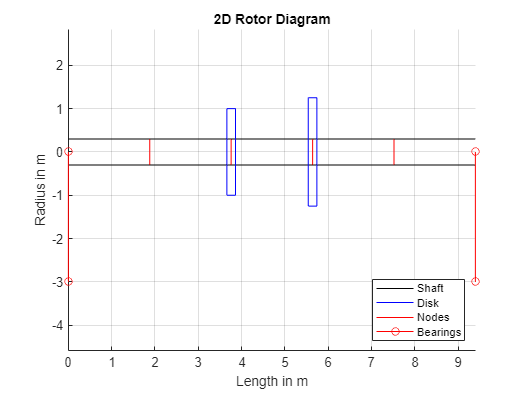


K = zeros(n*4);
for k = 0:n
    if 1+k*4 < n*4 - 4
        for i = 0:7
            for j = 0:7
                K(1+k*4+i,1+k*4+j) = K(1+k*4+i,1+k*4+j) + I_vec(k+1)*K_C(1+i,1+j)/I + K_F(1+i,1+j);
            end
        end
    end
end


%============== BEARINGS AND SEALS ================
n_bearings = [1 n];
speed_in = 4000; % RPM
[kxx(1) ,kxz(1) ,kzx(1) ,kzz(1) ,cxx(1) ,cxz(1) ,czx(1) ,czz(1)]= turb(speed_in);
[kxx(2) ,kxz(2) ,kzx(2) ,kzz(2) ,cxx(2) ,cxz(2) ,czx(2) ,czz(2)]= comp(speed_in);

[C, K] = bearings(kxx ,kxz ,kzx ,kzz ,cxx ,cxz ,czx ,czz ,n ,C, K);

syms omega
assume(omega,'real')
C = C*omega;
[A,B] = matrix(M,C,K,n);

%% ============== 2D Rotor Diagram ==============
for k = 1:4:(n-1)*4
    if round(k/4) > 0
        if r_s_vec(round(k/4)+1) <= r_s_vec(round(k/4))
            node = plot(L*round(k/4) + zeros(1,3) ,[-r_s_vec(round(k/4)) 0 r_s_vec(round(k/4))],'r-');
        else
            node = plot(L*round(k/4) + zeros(1,3) ,[-r_s_vec(round(k/4)+1) 0 r_s_vec(round(k/4)+1)],'r-');
        end
    end
%     node = plot(L*round(k/4) + zeros(1,3) ,[-r_s_vec(round(k/4)+1) 0 r_s_vec(round(k/4)+1)],'r-');
    hold on
    shaft = plot([L*round(k/4) L*round(k/4)+L] , r_s_vec(round(k/4)+1)*ones(1,2),'black');
    plot([L*round(k/4) L*(round(k/4)+1)] , -r_s_vec(round(k/4)+1)*ones(1,2),'black')
end
for k = 1:4:n*4
    if r_d_vec(round(k/4)+1) ~= 0
        disk = plot((L*round(k/4) - b_d_vec(round(k/4)+1)/2)*ones(1,3) ,[-r_d_vec(round(k/4)+1) 0 r_d_vec(round(k/4)+1)],'blue');
        plot((L*round(k/4) + b_d_vec(round(k/4)+1)/2)*ones(1,3) ,[-r_d_vec(round(k/4)+1) 0 r_d_vec(round(k/4)+1)],'blue');
        plot([(L*round(k/4) - b_d_vec(round(k/4)+1)/2) (L*round(k/4) + b_d_vec(round(k/4)+1)/2)] ,r_d_vec(round(k/4)+1)*ones(1,2),'blue');
        plot([(L*round(k/4) - b_d_vec(round(k/4)+1)/2) (L*round(k/4) + b_d_vec(round(k/4)+1)/2)] ,-r_d_vec(round(k/4)+1)*ones(1,2),'blue');
    end
end
% Bearings
for bearing = n_bearings -1
    bearing_new = plot((bearing*ones(1,3)*L) ,[-10*r_s -10*r_s 0],'ro-');
    ylabel('Radius in m')
    xlabel('Length in m')
    title('2D Rotor Diagram')
    legend([shaft, disk, node, bearing_new],{'Shaft', 'Disk','Nodes', 'Bearings'},'Location','southeast');
    grid on
end
axis equal
hold off

%======================================================
clear w

A_num = vpa(A,5);
B_num = vpa(B,5);
omega = speed_in*2*pi/60;
A_num_new = subs(A_num,'omega',omega);
[V_new,D_new]=eig(pinv(A_num_new)*(B_num));
w_sorted = sort(imag(diag(D_new)),'ascend');
w(:,1) = w_sorted;
F = w./(2*pi);
F(n*4:n*6)

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 9.0168269831962928291997384532551\\ 9.4587036920909576093024319752049\\ 36.672303328541209149098210720112\\ 47.916253983744796747255952240192\\ 80.105160665838973798451009776593\\ 110.4351702418429321907039223622\\ 149.04607009213431292035865325487\\ 152.19552683097051171272768301371 \end{array}\right)$$

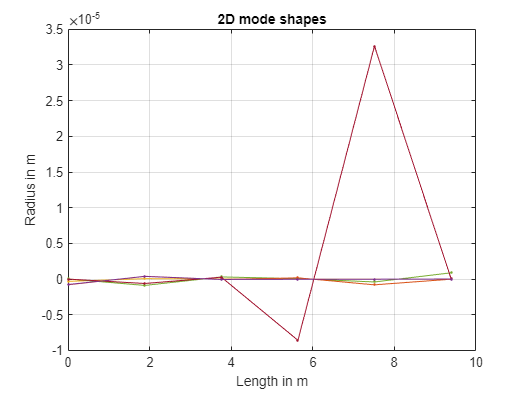

r = diag(1./D_new);
R = real(V_new);
I = imag(V_new);
omeg = imag(r);
realr = real(r);

for i=10:20
    % for k = 1:4:n*4
    %     z = L*round(k/4)
    %     plot(z,R(k,i),'r.-')
    %     hold on
    % end
    
    plot(L*round((1:4:n*4)/4),R((1:4:n*4)+n*4,i),'.-')
    hold on
    grid on
    ylabel('Radius in m')
    xlabel('Length in m')
    title('2D mode shapes')
end
hold off

## campbell

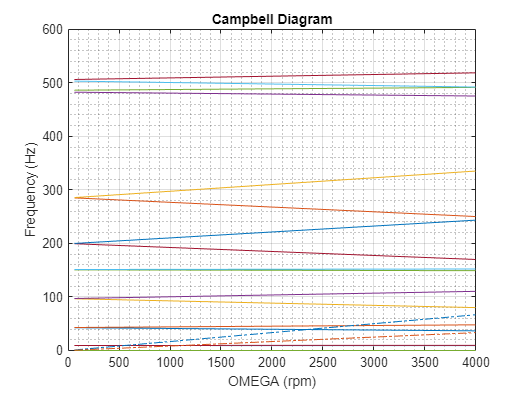


% First Method === eigenvalue-eigenvector sorting ===
% This Code is to be used as an Extention to the MAIN Code

clear w F F_unsorted

stop = 4000;
i = 1;
for speed = [60, stop]  % in rad/s
    [kxx(1) ,kxz(1) ,kzx(1) ,kzz(1) ,cxx(1) ,cxz(1) ,czx(1) ,czz(1)]= turb(speed);
    [kxx(2) ,kxz(2) ,kzx(2) ,kzz(2) ,cxx(2) ,cxz(2) ,czx(2) ,czz(2)]= comp(speed);
    [C_new, K_new] = bearings(kxx ,kxz ,kzx ,kzz ,cxx ,cxz ,czx ,czz ,n ,C, K);
    omega = speed*2*pi/60;
    [A,B] = matrix(M,C_new,K_new,n);
    A_num = vpa(A,5);
    B_num = vpa(B,5);
    A_num_new = subs(A_num,'omega',omega);
%     [V_new,D_new]=eig(lsqminnorm(double(A_num_new),double(B_num)));
    [V_new,D_new]=eig(pinv(A_num_new)*(B_num));
    [w_sorted,ind] = sort(imag(diag(D_new)),'ascend');
    F_unsorted(:,i) = imag(diag(D_new))./(2*pi);
    w(:,i) = w_sorted;
    i = i+1;
    F = w./(2*pi);
    if omega == 60*2*pi/60
        V_new_sorted = V_new(:,ind);
    else
        V_new_sorted2 = V_new(:,ind);
    end
end
% [eigvector, eigvalue]=eig(A - (lan).*B)

omega= [60,stop];
plot(omega,F(n*4:n*4+20,:))        % Colision With y-axis (F) verified using (F0 = nat_freq/2pi)
grid on
grid minor
hold on 
plot(omega,omega/60, '-.')
plot(omega,0.5*omega/60, '-.')
title('Campbell Diagram')
xlabel('OMEGA (rpm)')
ylabel('Frequency (Hz)')
hold off

F(n*4:n*4+20,:)

$$ans = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 9.2484323313687655207476240191796 & 9.0170019041345881497357469694374\\ 9.3731954995895292329735119302667 & 9.4589199443963441680942345644877\\ 42.494532531012792992258129166259 & 36.672452898989525458782646377457\\ 42.875494595014321709216669003912 & 47.916379780663786598652991171434\\ 96.592537844111636517832179973839 & 80.10526228263413610619979425955\\ 97.110855769450333052001897801235 & 110.43532910015224738298482535025\\ 150.65012670593341734447491027476 & 149.04618876966813945787381021779\\ 151.23770891835547249965279575912 & 152.19566496473538337451210734576\\ 199.41758344232423639115335283946 & 170.00386486142758109016246435553\\ 199.91227230930853400272186454933 & 243.42477344555422739487355565469\\ 285.04531395269331158006099656381 & 250.22023114560999609101276414206\\ 285.56990014682063755444797261733 & 335.13423606209580317008539472845\\ 482.45330539694124504741312099124 & 475.31202034346867139751351303621\\ 486.18774187530610200987361429569 & 491.39396615416540924296580580832\\ 503.17964844572996246313147022504 & 492.05434714865599269834250874865\\ 506.20246561306838352130815866365 & 518.62748405057763426085919501789 \end{array}\right)$$

% omega= [60,4000];
% plot(omega,F_unsorted)        % Colision With y-axis (F) verified using (F0 = nat_freq/2pi)
% grid on
% grid minor
% hold on 
% plot(omega,omega/60, '-.')
% plot(omega,0.5*omega/60, '-.')
% title('Campbell Diagram')
% xlabel('OMEGA (rpm)')
% ylabel('Frequency (Hz)')
% hold off
syms x
y1(x) = x/60;
num = 1;
for i = n*4:n*8
    y2(x) = ((F(i,2)-F(i,1))/(4000-60))*(x - 60) + F(i,1);
    if vpasolve(y1 == y2) ~= 0
        crit_speed(num) = vpasolve(y1 == y2);
    end
    num = num+1;
end
crit_speed'

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 553.16785793198334755673537904178\\ 563.04843374736054039815125725827\\ 2346.9118097149566230215960307994\\ 2781.4403620680251487191499784046\\ 4644.4981858554435257202336062126\\ 7294.6370604122617480876837121286\\ 8824.9204686303563192504027511754\\ 9207.7108331183960559876850443961\\ 8282.1509381483309245503301339285\\ 35435.485112382993473345620042304\\ 11196.621094112289786246877884398\\ 69690.007226226121564796293268132\\ 26113.830363960701213078512775441\\ 31678.023743971367977450538703843\\ 25825.556832850262996945830694372\\ 37446.102435224897723514713801053\\ 57390.255996678949840670481788248\\ 57363.699473865479572662624538615\\ 66407.884555882659591581402398325\\ 70211.22620643111756008968256377 \end{array}\right)$$

function [K11_fit_t ,K12_fit_t ,K21_fit_t ,K22_fit_t ,D11_fit_t ,D12_fit_t ,D21_fit_t ,D22_fit_t] = turb(speed_in)
method = 'cubicinterp';
speed_t = [367.8893038, 594.9139299, 964.0472719, 1495.62474, 2253.969678, 3272.634911, 6452.897062, 10064.89605, 14548.34974, 54432.60107];
K11_t = [1.96E+09, 1.31E+09, 9.07E+08, 7.03E+08, 5.52E+08, 4.67E+08, 4.23E+08, 4.75E+08, 5.55E+08, 1.24E+09];
K12_t = [2.69E+09, 1.69E+09, 1.08E+09, 6.90E+08, 3.55E+08, 1.98E+08, -2.94E+08, -8.76E+08, -1.59E+09, -6.98E+09];
K21_t = [7.65E+09, 5.18E+09, 3.64E+09, 2.83E+09, 2.26E+09, 1.95E+09, 1.74E+09, 1.75E+09, 2.03E+09, 5.57E+09];
K22_t = [2.42E+10, 1.54E+10, 1.04E+10, 7.46E+09, 5.43E+09, 4.52E+09, 3.75E+09, 4.13E+09, 5.16E+09, 1.69E+10];
D11_t = [1.12E+07, 4.66E+06, 2.23E+06, 1.55E+06, 1.11E+06, 8.13E+05, 7.18E+05, 6.98E+05, 6.89E+05, 5.73E+05];
D12_t = [2.89E+07, 9.77E+06, 3.49E+06, 2.07E+06, 1.01E+06, 2.62E+05, -3.17E+05, -6.29E+05, -8.34E+05, -1.03E+06];
D21_t = [2.80E+07, 9.30E+06, 3.27E+06, 2.03E+06, 1.08E+06, 2.93E+05, -3.19E+05, -6.32E+05, -8.38E+05, -1.04E+06];
D22_t = [2.51E+08, 1.08E+08, 4.91E+07, 2.75E+07, 1.65E+07, 1.02E+07, 5.80E+06, 4.69E+06, 4.47E+06, 4.26E+06];
K11_fit_t = fit(speed_t',K11_t',method);
K12_fit_t = fit(speed_t',K12_t',method);
K21_fit_t = fit(speed_t',K21_t',method);
K22_fit_t = fit(speed_t',K22_t',method);
D11_fit_t = fit(speed_t',D11_t',method);
D12_fit_t = fit(speed_t',D12_t',method);
D21_fit_t = fit(speed_t',D21_t',method);
D22_fit_t = fit(speed_t',D22_t',method);
if speed_in < speed_t(1)
    K11_fit_t = K11_t(1);
    K12_fit_t = K12_t(1);
    K21_fit_t = K21_t(1);
    K22_fit_t = K22_t(1);
    D11_fit_t = D11_t(1);
    D12_fit_t = D12_t(1);
    D21_fit_t = D21_t(1);
    D22_fit_t = D22_t(1);
elseif speed_in > speed_t(end)
    K11_fit_t = K11_t(end);
    K12_fit_t = K12_t(end);
    K21_fit_t = K21_t(end);
    K22_fit_t = K22_t(end);
    D11_fit_t = D11_t(end);
    D12_fit_t = D12_t(end);
    D21_fit_t = D21_t(end);
    D22_fit_t = D22_t(end);
else
    K11_fit_t = K11_fit_t(speed_in);
    K12_fit_t = K12_fit_t(speed_in);
    K21_fit_t = K21_fit_t(speed_in);
    K22_fit_t = K22_fit_t(speed_in);
    D11_fit_t = D11_fit_t(speed_in);
    D12_fit_t = D12_fit_t(speed_in);
    D21_fit_t = D21_fit_t(speed_in);
    D22_fit_t = D22_fit_t(speed_in);
end
end
function [K11_fit_c ,K12_fit_c ,K21_fit_c ,K22_fit_c ,D11_fit_c ,D12_fit_c ,D21_fit_c ,D22_fit_c] = comp(speed_in)
method = 'cubicinterp';
speed_c = [387.2429791, 626.2107655, 1014.763228, 1574.305569, 2372.545013, 3444.799508, 6792.366771, 10594.38339, 15313.69963, 57296.15507];
K11_c = [1.86E+09, 1.24E+09, 8.60E+08, 6.66E+08, 5.23E+08, 4.42E+08, 4.01E+08, 4.50E+08, 5.26E+08, 1.18E+09];
K12_c = [2.55E+09, 1.60E+09, 1.03E+09, 6.54E+08, 3.36E+08, 1.88E+08, -2.78E+08, -8.30E+08, -1.51E+09, -6.61E+09];
K21_c = [7.25E+09, 4.90E+09, 3.45E+09, 2.68E+09, 2.14E+09, 1.85E+09, 1.65E+09, 1.66E+09, 1.92E+09, 5.27E+09];
K22_c = [2.29E+10, 1.46E+10, 9.85E+09, 7.07E+09, 5.15E+09, 4.28E+09, 3.55E+09, 3.91E+09, 4.88E+09, 1.61E+10];
D11_c = [1.01E+07, 4.19E+06, 2.00E+06, 1.39E+06, 1.00E+06, 7.31E+05, 6.46E+05, 6.28E+05, 6.20E+05, 5.15E+05];
D12_c = [2.61E+07, 8.79E+06, 3.14E+06, 1.86E+06, 9.12E+05, 2.36E+05, -2.86E+05, -5.66E+05, -7.51E+05, -9.29E+05];
D21_c = [2.52E+07, 8.37E+06, 2.94E+06, 1.83E+06, 9.71E+05, 2.64E+05, -2.87E+05, -5.69E+05, -7.54E+05, -9.32E+05];
D22_c = [2.26E+08, 9.69E+07, 4.42E+07, 2.47E+07, 1.48E+07, 9.22E+06, 5.22E+06, 4.22E+06, 4.02E+06, 3.83E+06];
K11_fit_c = fit(speed_c',K11_c',method);
K12_fit_c = fit(speed_c',K12_c',method);
K21_fit_c = fit(speed_c',K21_c',method);
K22_fit_c = fit(speed_c',K22_c',method);
D11_fit_c = fit(speed_c',D11_c',method);
D12_fit_c = fit(speed_c',D12_c',method);
D21_fit_c = fit(speed_c',D21_c',method);
D22_fit_c = fit(speed_c',D22_c',method);
if speed_in < speed_c(1)
    K11_fit_c = K11_c(1);
    K12_fit_c = K12_c(1);
    K21_fit_c = K21_c(1);
    K22_fit_c = K22_c(1);
    D11_fit_c = D11_c(1);
    D12_fit_c = D12_c(1);
    D21_fit_c = D21_c(1);
    D22_fit_c = D22_c(1);
elseif speed_in > speed_c(end)
    K11_fit_c = K11_c(end);
    K12_fit_c = K12_c(end);
    K21_fit_c = K21_c(end);
    K22_fit_c = K22_c(end);
    D11_fit_c = D11_c(end);
    D12_fit_c = D12_c(end);
    D21_fit_c = D21_c(end);
    D22_fit_c = D22_c(end);
else
    K11_fit_c = K11_fit_c(speed_in);
    K12_fit_c = K12_fit_c(speed_in);
    K21_fit_c = K21_fit_c(speed_in);
    K22_fit_c = K22_fit_c(speed_in);
    D11_fit_c = D11_fit_c(speed_in);
    D12_fit_c = D12_fit_c(speed_in);
    D21_fit_c = D21_fit_c(speed_in);
    D22_fit_c = D22_fit_c(speed_in);
end
end
function [C_new, K_new] = bearings(kxx ,kxz ,kzx ,kzz ,cxx ,cxz ,czx ,czz ,n ,C, K)
C_new = C;
K_new = K;
n_bearings = [1 n];
size_n_bear = size(n_bearings);
for bearing = n_bearings
    k = bearing - 1;
    %     if 1+k*4 < n*4
    if k ~= n - 1
        K_bearing =-[kxx(size_n_bear(1))  kxz(size_n_bear(1)) 0 0;
                     kzx(size_n_bear(1))  kzz(size_n_bear(1)) 0 0;
                     0   0 0   0;
                     0   0 0   0];
    else
        K_bearing =-[kxx(size_n_bear(2))  kxz(size_n_bear(2)) 0 0;
                     kzx(size_n_bear(2))  kzz(size_n_bear(2)) 0 0;
                     0   0 0   0;
                     0   0 0   0];
    end
    for i = 0:3
        for j = 0:3
            K_new(1+k*4+i,1+k*4+j)= K(1+k*4+i,1+k*4+j) + K_bearing(1+i,1+j);
        end
    end
    %     end
    k = bearing - 1;
    %     if 1+k*4 < n*4
    if k ~= n - 1
        C_bearing =-[cxx(size_n_bear(1))  cxz(size_n_bear(1)) 0 0;
                     czx(size_n_bear(1))  czz(size_n_bear(1)) 0 0;
                     0   0 0   0;
                     0   0 0   0];
    else
        C_bearing =-[cxx(size_n_bear(2))  cxz(size_n_bear(2)) 0 0;
                     czx(size_n_bear(2))  czz(size_n_bear(2)) 0 0;
                     0   0 0   0;
                     0   0 0   0];
    end

    for i = 0:3
        for j = 0:3
            C_new(1+k*4+i,1+k*4+j)= C(1+k*4+i,1+k*4+j) + C_bearing(1+i,1+j);
        end
    end
    %     end
end
end
function [A,B] = matrix(M,C,K,n)
A = [zeros(n*4)  M;M  C];
B = [M  zeros(n*4);zeros(n*4)  -K];
end